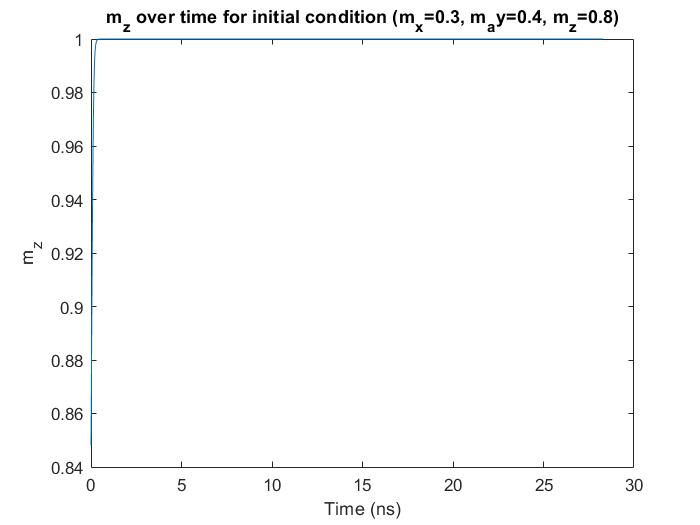

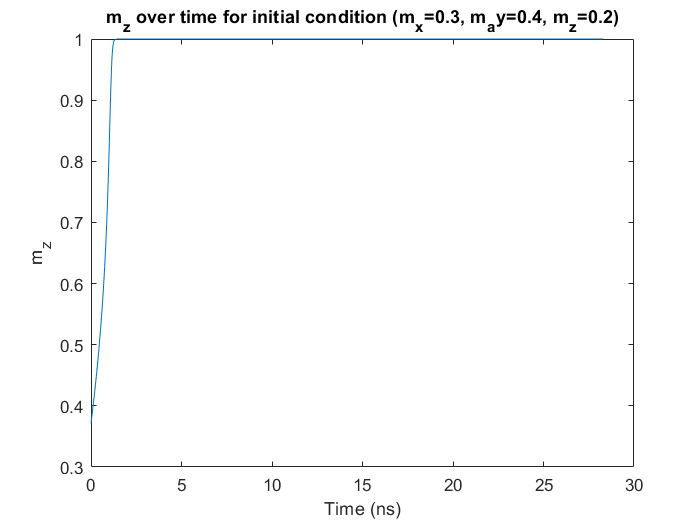

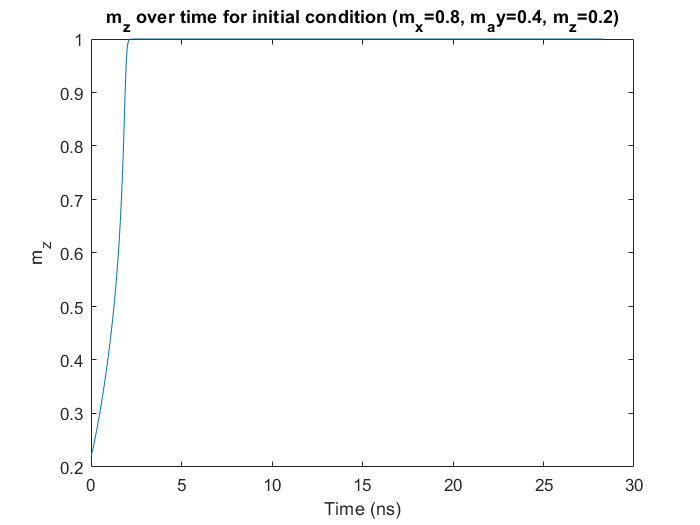

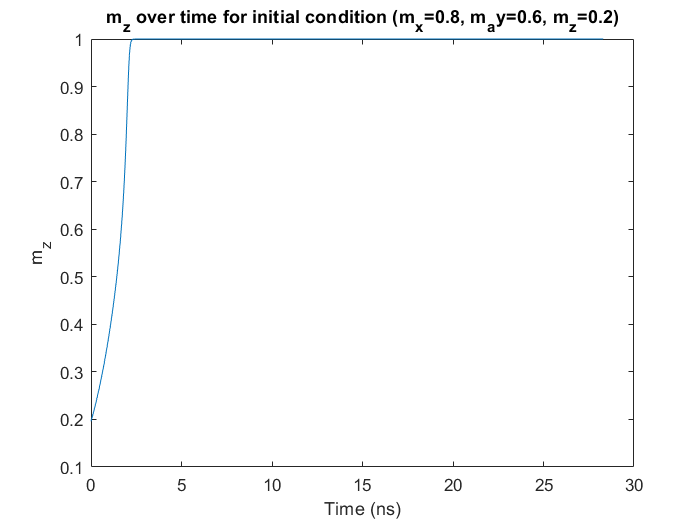

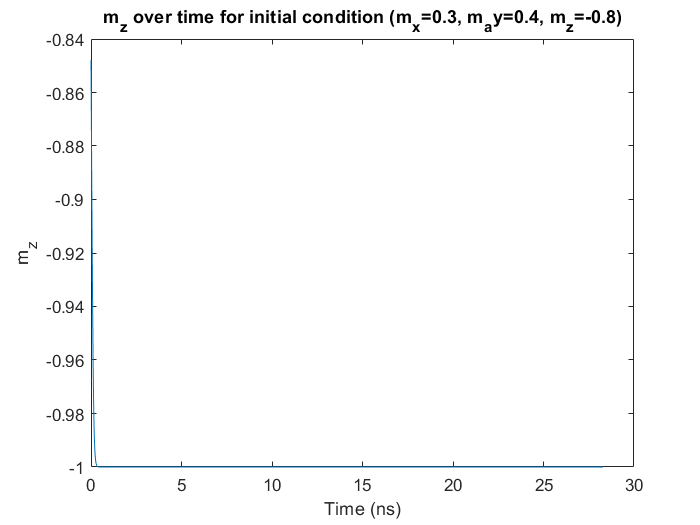

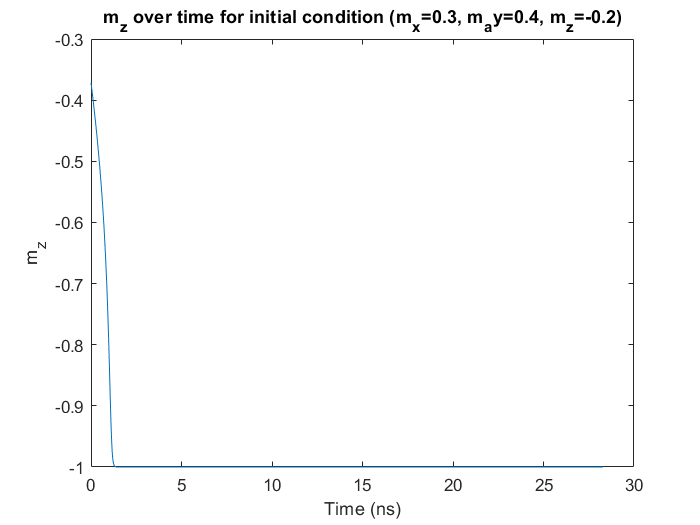

clc;
clear;
close all;

global alpha;
alpha = 0.01;
gamma = 2.21276e5;
mu = 1.2566e-6;
h_k = 3.1951e5;

tau1 = 0;
tau2 = 2000;
N = 1000;
h = (tau2 - tau1) / N;
tau = linspace(tau1, tau2, N+1);

m_initial = input('initial magnetization position: ');

n = size(m_initial, 1);
relaxation_times = zeros(n, 1);

for j = 1:n
    m_norm = m_initial(j, :) / norm(m_initial(j, :));
    m = zeros(N+1, 3);
    m(1, :) = m_norm;
    
    for i = 1:N
        k1 = h*llg(m(i, :), alpha);
        k2 = h*llg(m(i, :) + 0.5*k1, alpha);
        k3 = h*llg(m(i, :) + 0.5*k2, alpha);
        k4 = h*llg(m(i, :) + k3, alpha);

        m(i+1, :) = m(i, :) + (k1 + 2*k2 + 2*k3 + k4) / 6;
        m(i+1, :) = m(i+1, :) / (norm(m(i+1, :)) );
    end

    time = tau * (1 + alpha^2) / (gamma * h_k);

    rt = find(abs(m(:, 3)) >= 0.98, 1);
    if isempty(rt)
        relaxation_times(j) = NaN;
    else
        relaxation_times(j) = time(rt) * 1e9;
    end

    figure;
    plot(time * 1e9, m(:,3))
    xlabel('Time (ns)');
    ylabel('m_z');
    title(['m_z over time for initial condition (m_x=', num2str(m_initial(j, 1)), ', m_ay=', num2str(m_initial(j, 2)), ', m_z=', num2str(m_initial(j, 3)), ')']);

end


disp(table(m_initial(:, 1), m_initial(:, 2), m_initial(:, 3), relaxation_times,'VariableNames', {'m_x', 'm_y', 'm_z', 'Relaxation_Time_ns'}));

    m_x    m_y    m_z     Relaxation_Time_ns
    ___    ___    ____    __________________

    0.3    0.4     0.8         0.16975      
    0.3    0.4     0.2          1.1882      
    0.8    0.4     0.2          2.0087      
    0.8    0.6     0.2          2.1784      
    0.3    0.4    -0.8         0.16975      
    0.3    0.4    -0.2          1.1882      



function llg = llg(m, alpha)
H = [0, 0, m(3)];
dynamic = cross(m, H);
damping = cross(m, dynamic);
llg = -dynamic - alpha * damping;
end

